# CLUSTERING

## DATA GENERATION and PATH SETTINGS

Add depencies to Path:

The implementation of Optics used can be found at this link:

[https://github.com/alexgkendall/OPTICS_Clustering](https://github.com/alexgkendall/OPTICS_Clustering)

clc; clear; close all
addpath('OPTICS_Clustering-master\')

Generation of a simple dataset of Gaussian clusters, bivariate Gaussian random variables,

using the Affine Transformation:

        $\mathbf{y}=\mathbf{Ax}+\mathbf{b}$Still, the vector $\mathbf{y}$ is Gaussian.

% Generate a dataset with gaussian random clusters
% bivariate random variables with zero mean a the identity as covariance matrix
randNPointsV1 = randn(1000,2);
randNPointsV2 = randNPointsV1;
randNPointsV3 = randNPointsV1;
randNPointsV4 = randNPointsV1;

% Affine transformation of random variable -> remains random variables
meanV1  = [-20,40];
AV1 = [7 0; 0 7];
meanV2  = [40,-20];
AV2 = [6 2; 2 6];
meanV3  = [6,4];
AV3 = [12 10; 10 12];
meanV4  = [-20,-20];
AV4 = [4 -1; -1 4];

for i = 1:1000
    randNPointsV1(i,:) = randNPointsV1(i,:)*AV1 + meanV1;
    randNPointsV2(i,:) = randNPointsV2(i,:)*AV2 + meanV2;
    randNPointsV3(i,:) = randNPointsV3(i,:)*AV3 + meanV3;
    randNPointsV4(i,:) = randNPointsV4(i,:)*AV4 + meanV4;
end

% Points
X = [randNPointsV1; randNPointsV2; randNPointsV3; randNPointsV4];
% Labels
grp = [ones(1000,1); 2*ones(1000,1); 3*ones(1000,1); 4*ones(1000,1)];

## Dataset Visualization

We can use grp with gscatter to highlight the 4 clusters plotted in the cartesian plane.

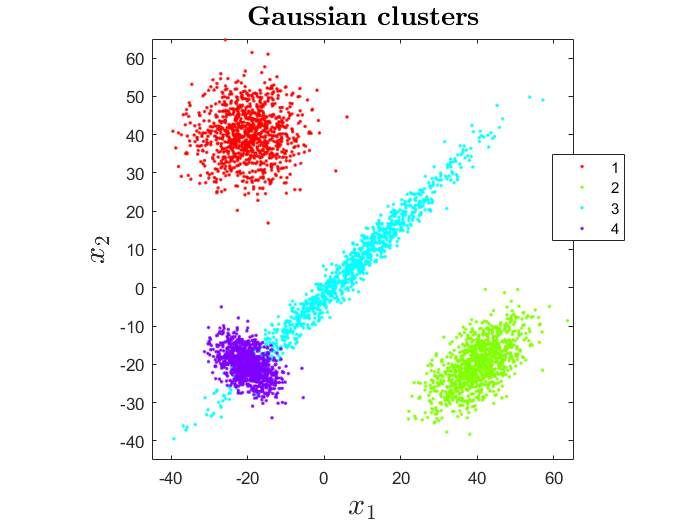

figure
gscatter(X(:,1),X(:,2),grp)
axis equal

xlim([-45 65])
ylim([-45 65])
xlabel('$x_1$',"FontSize",18,'interpreter','latex')
ylabel('$x_2$',"FontSize",18,'interpreter','latex')
title('\textbf{Gaussian clusters}','Interpreter','latex','FontSize',16)

Observe that the Silhouette coefficients of some points of the 3rd cluster (cyan cluster) are close to -1, mining that this evaluation metric may not be the best metric to assess cluster quality! Actually, this is related to the overlapping of clusters 3 and 4, which leads to a small value of the separateness of the two clusters for some points.

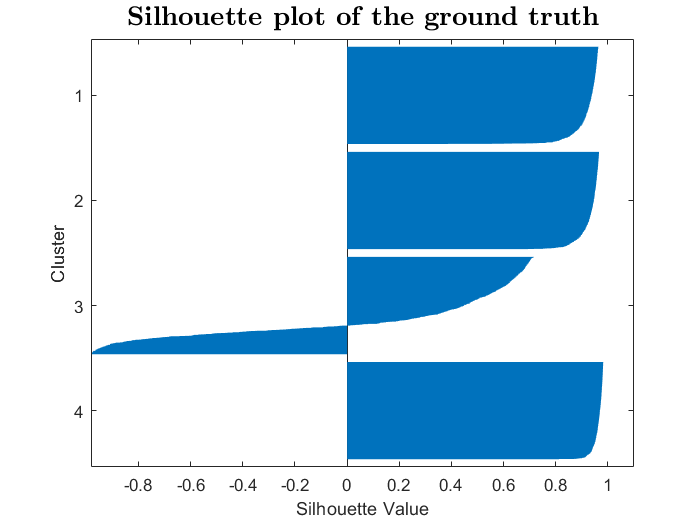

silhouette(X, grp)
title('\textbf{Silhouette plot of the ground truth}','Interpreter','latex','FontSize',16)

## k-means Clustering

Remember that this clustering algorithm requires the number of clusters as a parameter and works only with numerical data.

The clustering algorithm is sensitive to the starting positions (seeds) of the clusters, thus, the function kmeans calls the clustering algorithm more than one time (and this parameter can be changed using the "Replicates" option) in order to check across multiple runs the best result.

In our case, having the ground truth of the dataset we can just plug $k=4$.

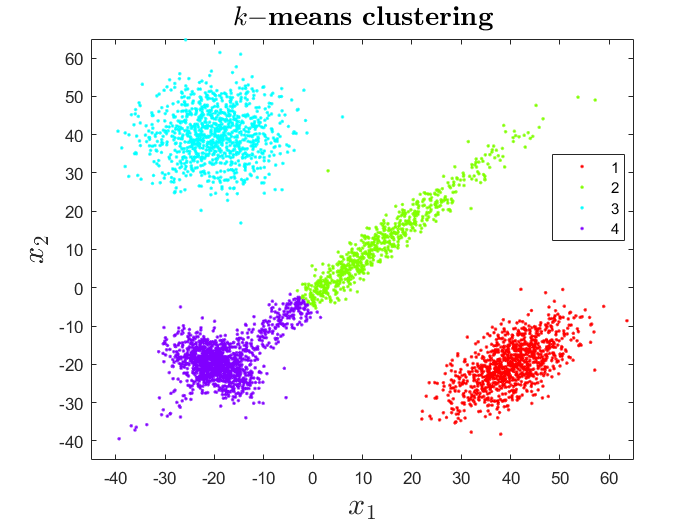

rng(1); % For reproducibility
idx = kmeans(X,4);
figure
gscatter(X(:,1),X(:,2),idx)
xlim([-45 65])
ylim([-45 65])
xlabel('$x_1$',"FontSize",18,'interpreter','latex')
ylabel('$x_2$',"FontSize",18,'interpreter','latex')
title('\textbf{$k-$means clustering}','Interpreter','latex','FontSize',16)

Paradoxically, the Silhouette plot obtained by the k-mans clustering is better than the one of the representative of the ground truth. However, even with a simple visualization we can understand that the result is suboptimal. This should not be suprising, since the presence of overlapping clusters is difficult to face with a partitioning method. Alternatively, one can use a soft clustering algorithm like, fuzzy c-means.

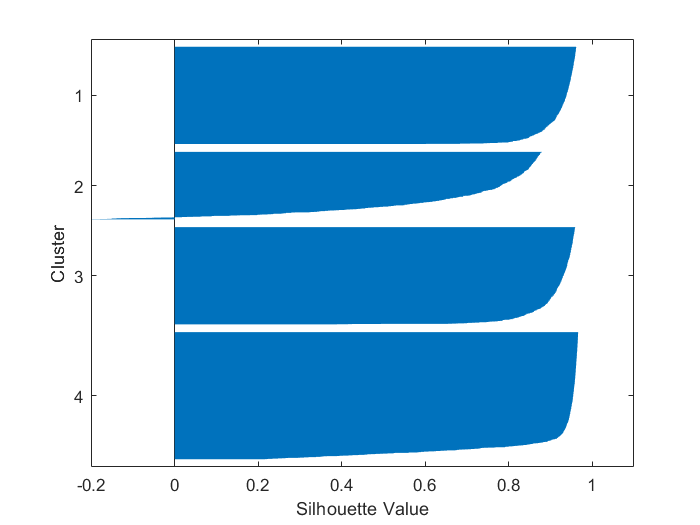

silhouette(X, idx)

## Gaussian Mixture Models

Also this clustering algorithm needs the number of clusters to search as a parameter. Furthermore, this algorithm works well in the assumption that the clusters are generated from multivariate (here bivariate) Gaussian distributions. In this case the result is particularly effective because the synthetic data have generated according to Gaussian distributions.

Using the function fitgmdist only builts the gaussian mixture model that best fit our data based on the Expectation-Maximization algorithm. To obtain clusters, we need to call the function cluster, calling the gaussian mixture model and our dataset. The function cluster with a gaussian mixture model allows also to return a matrix whose rows contain the probabilities that an observation belong to a specific cluster. This is the reason why this algorithm is a soft clustering algorithm: each point in the dataset has a (even small) probability to belong to every cluster. The cluster membership is assigned by selecting the cluster id with the maximum probability.

Contrary to other clustering methods (e.g. k-means), this algorithm does not necessarily converge to a solution.

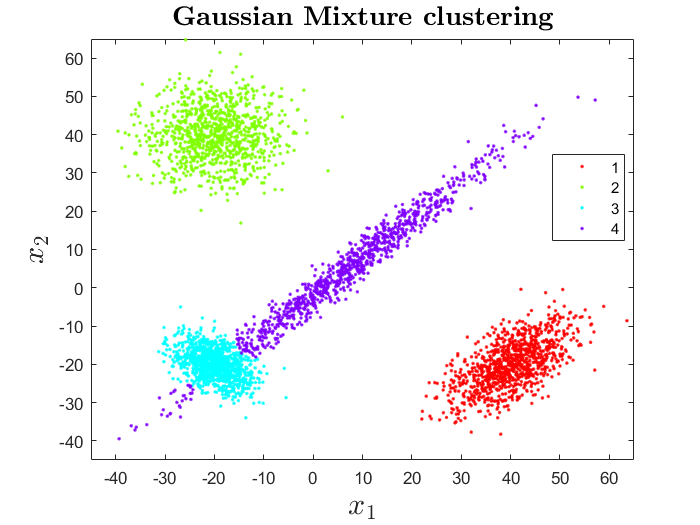

rng(2); % For reproducibility
gm = fitgmdist(X,4);       % built the gaussina mixture model
[idx,~,~] = cluster(gm,X); % Cluster data based on the gm model

figure
gscatter(X(:,1),X(:,2),idx)
xlim([-45 65])
ylim([-45 65])
xlabel('$x_1$',"FontSize",18,'interpreter','latex')
ylabel('$x_2$',"FontSize",18,'interpreter','latex')
title('\textbf{Gaussian Mixture clustering}','Interpreter','latex','FontSize',16)

## Hierarchical Clustering

This clustering algorithm works by building a data structure containing step by step which clusters are merged/splitted and which is they distance, measured with an appropriate linkage metric (check the presentation for further details).

Using the function Linkage, MATLAB operates in an agglomerative way, that means, starting from each point as a single cluster, at each iteration the two closest clusters (based on the selected linkage) are merged. The process terminates when we reach a unique cluster. The merging process of the algorithm can be visualized using a Dendrogram, which is a graphical representation of the data structure built by Linkage.

As well as for the Gaussian Mixture case, we can perform the clustering using the function cluster, e.g. specifing the number of clusters that we want or a threshold for "cutting" the dendrogram.

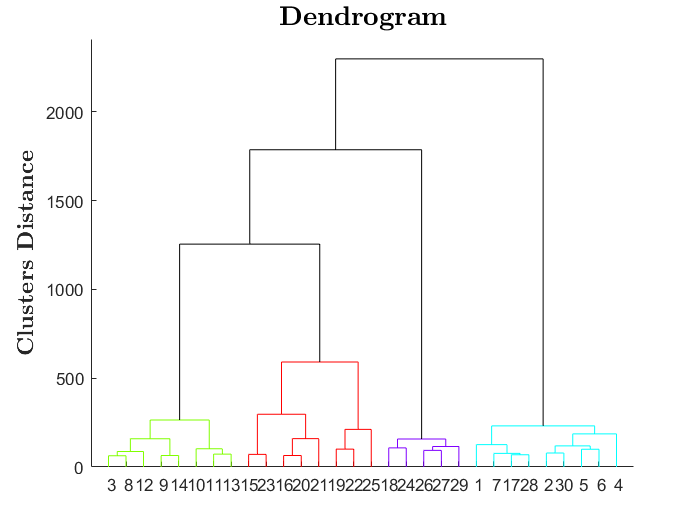

rng(3);
Z = linkage(X,"ward","euclidean");
dendrogram(Z,'ColorThreshold',1000)
title('\textbf{Dendrogram}','Interpreter','latex','FontSize',16)
ylabel('\textbf{Clusters Distance}',"FontSize",14,'interpreter','latex')

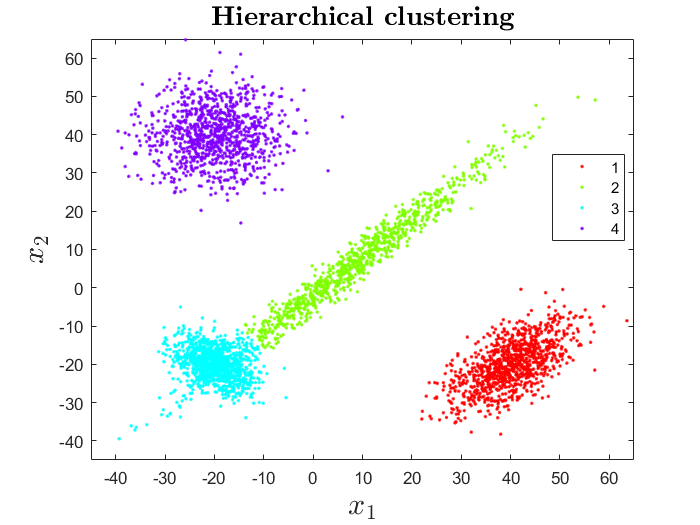

idx = cluster(Z, "maxclust", 4);

figure
gscatter(X(:,1),X(:,2),idx)
xlim([-45 65])
ylim([-45 65])
xlabel('$x_1$',"FontSize",18,'interpreter','latex')
ylabel('$x_2$',"FontSize",18,'interpreter','latex')
title('\textbf{Hierarchical clustering}','Interpreter','latex','FontSize',16)

## Density-based Clustering with Optics

Density-based clustering is an alternative approach based on the connectivity between points in the dataset. This is a very useful approach also for outlier detection, since these algorithms are able to spot clusters based on the density of their internal points. The two most famous algorithms are DBSCAN and OPTICS, but there are many others (DENCLUE, BIRCH, ...).

Here we propose a solution to this problem by using the algorithm Optics, not implemented as a built-in function in MATLAB. You can download its implementation in the link at the beginning of this livescript.

Optics does not cluster directly data. Similarly to the function Linkage, it builts up a representation of the dataset depending on the reachability distance of the datapoints, which is a measure of thir connectivity.  From this representation, we can select a threshold of the reachability distance to obtain a certain number of "valleys" in the reachability plot. Each valley corresponds to a group of points with a similar density, that means a cluster!

rng(4);
[RD, ~, order]=optics(X,400);
figure
hold on
area(1:4000,RD,'FaceColor','k')
movingAvg = movmean(RD,10);
movingMed = medfilt1(RD,10)

movingMed =    24.3050   49.0511   49.0511   49.0511   49.0511   50.8621   49.0511   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   48.6100   50.9217   50.9217   50.9217   52.2656   52.2656   50.1637   50.1637   48.3793   48.3793   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292   47.7292


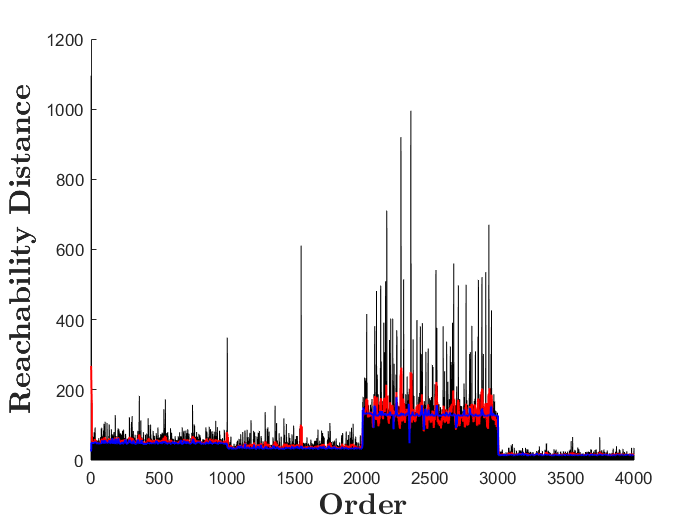

plot(1:4000,movingAvg,"Color","red","linewidth",1.2)
plot(1:4000,movingMed,"Color","blue","linewidth",1.2)
hold off
xlabel('\textbf{Order}',"FontSize",18,'interpreter','latex')
ylabel('\textbf{Reachability Distance}',"FontSize",18,'interpreter','latex')

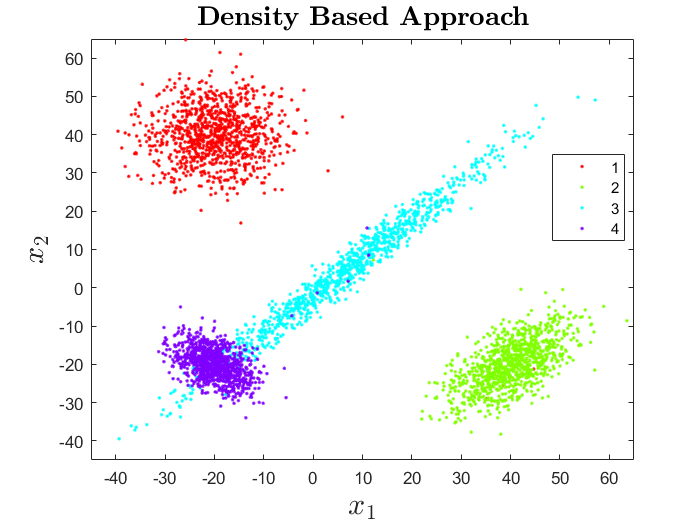

pks = [1 1003 2003 2993 4000];
Y = [X(order(pks(1):pks(2)),:);
     X(order(pks(2)+1:pks(3)),:);
     X(order(pks(3)+1:pks(4)),:);
     X(order(pks(4)+1:pks(5)),:)];
idx = [ones(pks(2)-pks(1)+1,1);
       2*ones(pks(3)-pks(2),1);
       3*ones(pks(4)-pks(3),1);
       4*ones(pks(5)-pks(4),1)];
 
figure
gscatter(X(:,1),X(:,2),idx)
xlim([-45 65])
ylim([-45 65])
xlabel('$x_1$',"FontSize",18,'interpreter','latex')
ylabel('$x_2$',"FontSize",18,'interpreter','latex')
title('\textbf{Density Based Approach}','Interpreter','latex','FontSize',16)

# A more challenging problem : recognizing worms in data

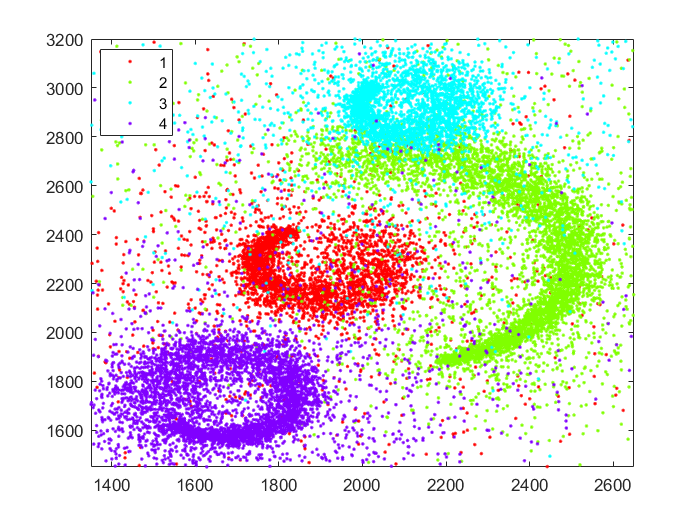

% Load 2d synthetic data
load worms_2.txt
% Load ground truth labels
load worms_2-labels.txt

figure
gscatter(worms_2(:,1),worms_2(:,2),worms_2_labels(:,1))

xlim([1350 2650])
ylim([1450 3200])

eva = evalclusters(worms_2,'kmeans','silhouette','KList',2:10);

eva2 = evalclusters(worms_2,'gmdistribution','silhouette','KList',2:10);

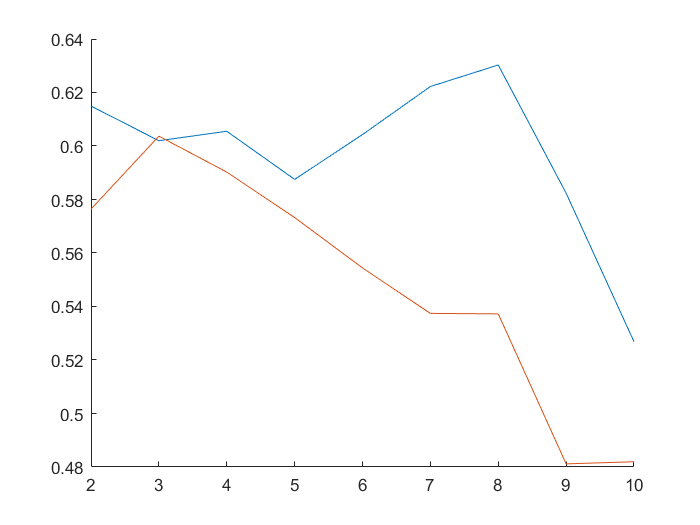

figure
hold on
plot(2:10,eva.CriterionValues)
plot(2:10,eva2.CriterionValues)

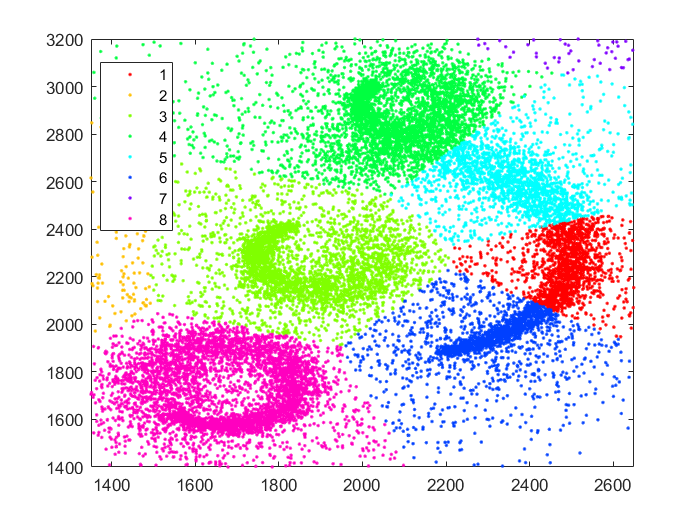

[~,kBest1] = max(eva.CriterionValues);
[~,kBest2] = max(eva2.CriterionValues);

rng(1); % For reproducibility
idx = kmeans(worms_2,kBest1+1);
figure
gscatter(worms_2(:,1),worms_2(:,2),idx)
xlim([1350 2650])
ylim([1450 3200])

xlim([0 4000])
ylim([180 4870])

xlim([1350 2650])
ylim([1400 3200])

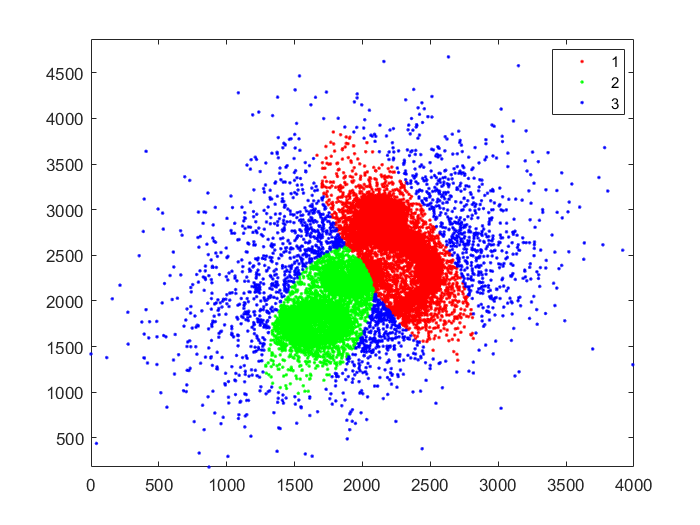

rng(1); % For reproducibility
gm = fitgmdist(worms_2,kBest2+1);
[idx,~,p] = cluster(gm,worms_2);
figure
gscatter(worms_2(:,1),worms_2(:,2),idx)
xlim([1350 2650])
ylim([1450 3200])   

xlim([0 4000])
ylim([180 4870])

Z1 = linkage(worms_2,"ward","euclidean");
Z2 = linkage(worms_2,"complete","euclidean")

Z2 = 	1.0e+04 *

    1.8155    1.8492    0.0000
    1.4798    1.5060    0.0000
    1.4791    1.4843    0.0000
    0.3533    0.3560    0.0000
    1.0748    1.2513    0.0000
    1.2579    1.3024    0.0000
    1.4502    1.4598    0.0000
    1.1651    1.1764    0.0000
    1.1919    1.2033    0.0000
    0.7114    0.7207    0.0000


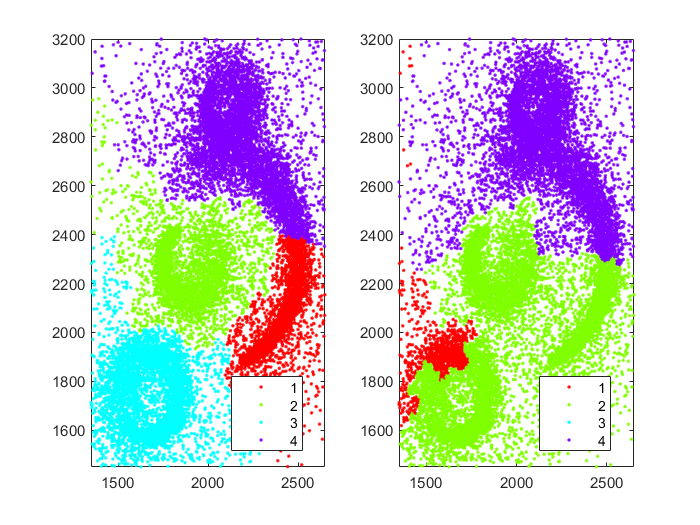

grp1 = cluster(Z1, "maxclust", 4);
grp2 = cluster(Z2, "maxclust", 4);

figure
subplot(121)
gscatter(worms_2(:,1),worms_2(:,2),grp1)
xlim([1350 2650])
ylim([1450 3200])

subplot(122)
gscatter(worms_2(:,1),worms_2(:,2),grp2)
xlim([1350 2650])
ylim([1450 3200])

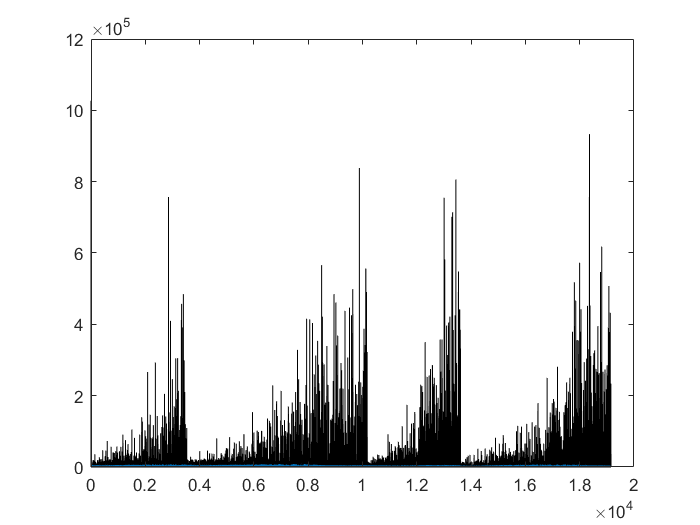


[RD, CD, order]=optics(worms_2,600);
figure
area(order,RD(order))

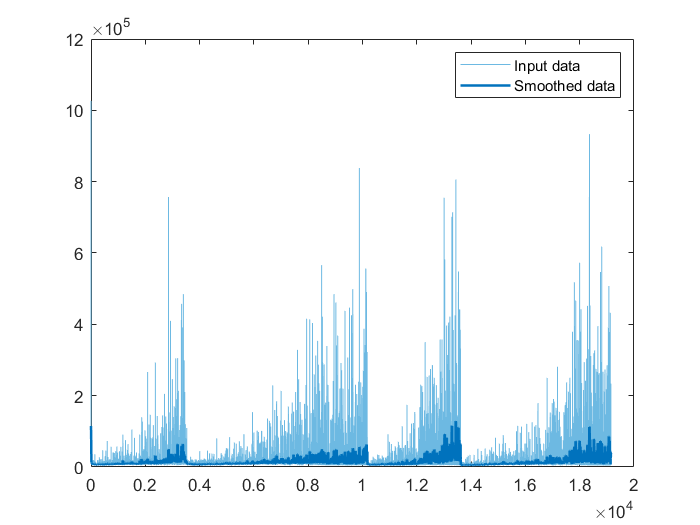

% Smooth input data
smoothedData = smoothdata(RD,'movmean',20);

% Visualize results
clf
plot(RD,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

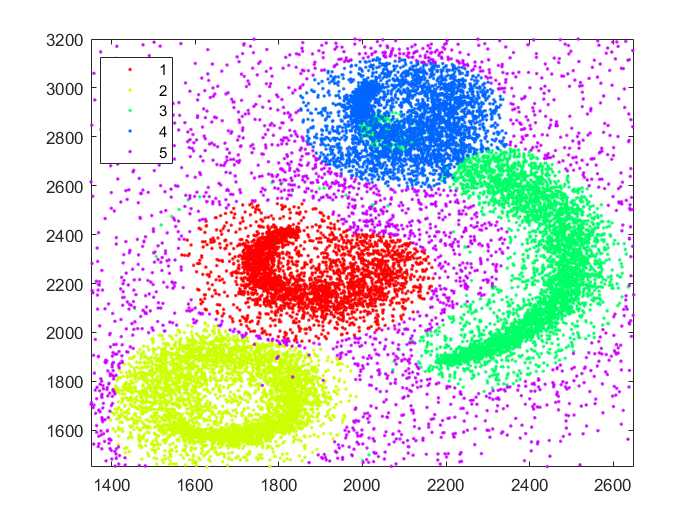

peaks = [3000, 3200, 7568, 8200, 12800, 12800, 16100];
data01 = worms_2(order(1:peaks(1)),:);
data02 = worms_2(order(peaks(2)+1:peaks(3)),:);
data03 = worms_2(order(peaks(4)+1:peaks(5)),:);
data04 = worms_2(order(peaks(6)+1:peaks(7)),:);

noise = [worms_2(order(peaks(1)+1:peaks(2)),:);  
         worms_2(order(peaks(3)+1:peaks(4)),:);
         worms_2(order(peaks(5)+1:peaks(6)),:);
         worms_2(order(peaks(7)+1:end),:);];
data = [data01; data02; data03; data04; noise];
grpOptics = [ones(peaks(1),1)
             2*ones(peaks(3)-peaks(2),1)
             3*ones(peaks(5)-peaks(4),1)
             4*ones(peaks(7)-peaks(6),1)
             5*ones(peaks(2)-peaks(1),1)
             5*ones(peaks(4)-peaks(3),1)
             5*ones(peaks(6)-peaks(5),1)
             5*ones(19152-peaks(7),1)];
figure
gscatter(data(:,1),data(:,2),grpOptics)
xlim([1350 2650])
ylim([1450 3200])